# **Week 6: Examining Non-Linear Effects through the NLSE**

The code below examines the the non-linear effects in an optic fibre, in addition to attenuation and chromatic dispersion, through the solution of the non-linear Schrodinger equation using the split step Fourier method

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

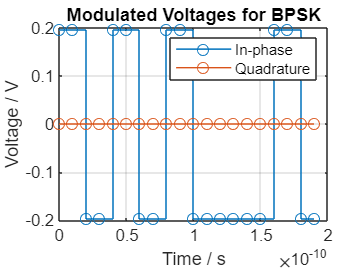

clear all; clearvars;

% Parameters
NSymb = 500000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
SNR_vals = [1:11];
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevels = [-pi/16, pi/16]'; % Discrete voltage levels for BPSK and QPSK
DCOffset = 0; % DC offset of modulated current in V

% -------------------------------------------------------------------------------

% FOR BPSK:
% Generating random bit sequence(s)
sourceBitsBPSK = randi([0 1], NSymb, length(SNR_vals)); % Matrix of source bits for BPSK
sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));

vI_BPSK(real(sourceSymbolsBPSK)>0) = voltageLevels(2); % Maps 1 -> pi/16
vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevels(1); % Maps -1 -pi/16

vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase voltage
stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltages for BPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

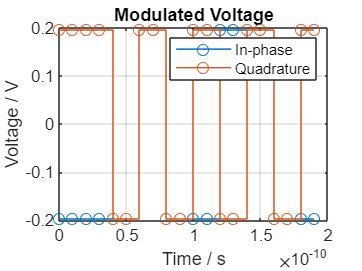


% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, length(SNR_vals)); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/16
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/16
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/16
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/16

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### IQ Modulation

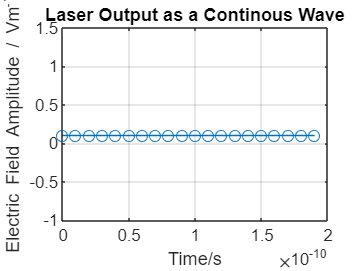

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 10;
laserPw_Lin = (1e-3)*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

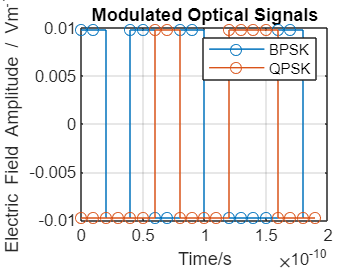


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

modOpticSigBPSK = IQModulatorModified(vI_BPSK_upsampled, vQ_BPSK_upsampled, laserE, Vpi);
modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);

% Visualising modulated optical signals
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "o-");
hold on
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("BPSK", "QPSK")
grid on
hold off

## Optical Channel

### Adding AWGN

% Adding AWGN 
laserEMag = sqrt(laserPw_Lin);
modLaserSymbs = laserEMag*0.5*sin(0.5*[-pi/16, pi/16]*pi/Vpi); % Symbol values in the modulated laser output
powerPerSymb = mean(modLaserSymbs.^2);
 
modOpticSigBPSK_AWGN = zeros(size(modOpticSigBPSK)); modOpticSigQPSK_AWGN = zeros(size(modOpticSigQPSK));
for i=1:length(SNR_vals)
    SNRb_Lin(i,1) = 10^(SNR_vals(i)/10); % linear SNR per symbol
    AWGN_StdDev(i,1) = sqrt(powerPerSymb/SNRb_Lin(i,1)); % AWGN Standard deviation

    modOpticSigBPSK_AWGN(:,i) = modOpticSigBPSK(:,i) + (1/sqrt(2))*AWGN_StdDev(i,1)*(randn(size(modOpticSigBPSK, 1),1) + 1i*randn(size(modOpticSigBPSK, 1),1));
    modOpticSigQPSK_AWGN(:,i) = modOpticSigQPSK(:,i) + (1/sqrt(2))*AWGN_StdDev(i,1)*(randn(size(modOpticSigQPSK, 1),1) + 1i*randn(size(modOpticSigQPSK, 1),1));
end

### Adding Attenuation, CD and/or Non-Linear Effects through the NLSE

fibreParams = struct("alpha", 0.2, "gamma", 1.3, "linkLength", 50, "D", 17); % Fibre parameters to be used in the SSF
stepSize = 1; % Step size for SSF method in km
CLambda = 1550e-9; % Central wavelength of optical carrier in m

% Solving the NLSE using the SSF
channelOutBPSK = SplitStepFourier(modOpticSigBPSK, SpS, Rs, CLambda, fibreParams, stepSize); % BPSK without AWGN
channelOutQPSK = SplitStepFourier(modOpticSigQPSK, SpS, Rs, CLambda, fibreParams, stepSize); % QPSK without AWGN
channelOutBPSK_AWGN = SplitStepFourier(modOpticSigBPSK_AWGN, SpS, Rs, CLambda, fibreParams, stepSize); % BPSK with AWGN
channelOutQPSK_AWGN = SplitStepFourier(modOpticSigQPSK_AWGN, SpS, Rs, CLambda, fibreParams, stepSize); % QPSK with AWGN


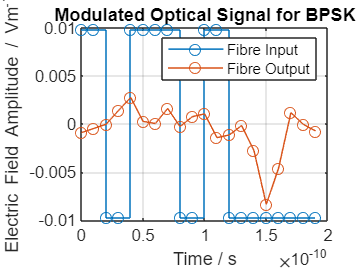

% Visualising optical signals before and after noise and attenuation
% BPSK without AWGN
stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutBPSK(1:10*SpS,11)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for BPSK")
legend("Fibre Input", "Fibre Output")
grid on
hold off

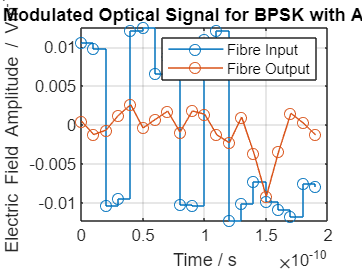


% BPSK with AWGN
stairs(t(1:10*SpS), real(modOpticSigBPSK_AWGN(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutBPSK_AWGN(1:10*SpS,11)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for BPSK with AWGN")
legend("Fibre Input", "Fibre Output")
grid on
hold off

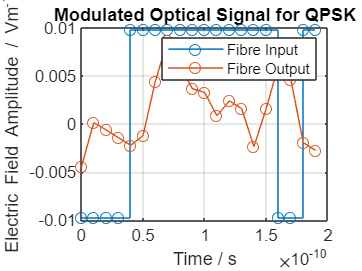


% QPSK without AWGN
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK(1:10*SpS,11)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK")
legend("Fibre Input", "Fibre Output")
grid on
hold off

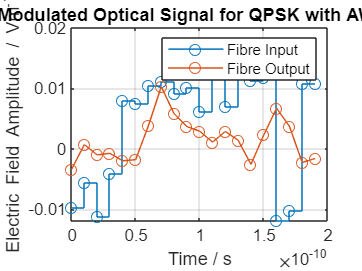


% QPSK without AWGN
stairs(t(1:10*SpS), real(modOpticSigQPSK_AWGN(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK_AWGN(1:10*SpS,11)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK with AWGN")
legend("Fibre Input", "Fibre Output")
grid on
hold off

## Receiver

### Optical Front-End

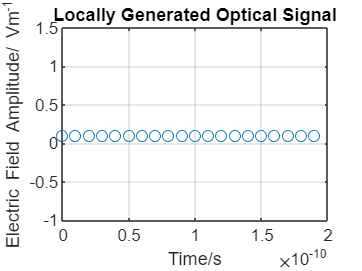

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source

% Visualising locally generated optical signal
plot(t(1:20), real(Elo(1:20,1)), "o");
title("Locally Generated Optical Signal");
xlabel("Time/s")
ylabel("Electric Field Amplitude/ Vm^{-1}")
grid on


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

% Computing output from optical front-end 
count = 1;
for i=1:length(SNR_vals)  % Output from Optical Front-End
    % Solution to NLSE without AWGN
    OpticFEOutBPSK(:,count:count+1) = OpticalFrontEnd(channelOutBPSK(:,i), Elo, eta_ph, 1);
    OpticFEOutQPSK(:,count:count+1) = OpticalFrontEnd(channelOutQPSK(:,i), Elo, eta_ph, 1);
    
    % Solution to NLSE with AWGN
    OpticFEOutBPSK_AWGN(:,count:count+1) = OpticalFrontEnd(channelOutBPSK_AWGN(:,i), Elo, eta_ph, 1);
    OpticFEOutQPSK_AWGN(:,count:count+1) = OpticalFrontEnd(channelOutQPSK_AWGN(:,i), Elo, eta_ph, 1);

    % Test signals with no added AWGN
    testFEOutBPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigBPSK(:,i), Elo, eta_ph, 1);
    testFEOutQPSK(:,count:count+1) = OpticalFrontEnd(modOpticSigQPSK(:,i), Elo, eta_ph, 1);

    count = count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
% BPSK
OpticFEOutBPSK_I = TIA_Gain*OpticFEOutBPSK(:, 1:2:end); OpticFEOutBPSK_Q = TIA_Gain*OpticFEOutBPSK(:, 2:2:end); % Without AWGN
OpticFEOutBPSK_AWGN_I = TIA_Gain*OpticFEOutBPSK_AWGN(:, 1:2:end); OpticFEOutBPSK_AWGN_Q = TIA_Gain*OpticFEOutBPSK_AWGN(:, 2:2:end); % With AWGN
testFEOutBPSK_I = TIA_Gain*testFEOutBPSK(:, 1:2:end); testFEOutBPSK_Q = TIA_Gain*testFEOutBPSK(:, 2:2:end); % Test

% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:, 1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:, 2:2:end); % Without AWGN
OpticFEOutQPSK_AWGN_I = TIA_Gain*OpticFEOutQPSK_AWGN(:, 1:2:end); OpticFEOutQPSK_AWGN_Q = TIA_Gain*OpticFEOutQPSK_AWGN(:, 2:2:end); % With AWGN
testFEOutQPSK_I = TIA_Gain*testFEOutQPSK(:, 1:2:end); testFEOutQPSK_Q = TIA_Gain*testFEOutQPSK(:, 2:2:end); % Test



## DSP

### Scaling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
scaleFactor = sin(voltageLevels(2))*TIA_Gain*eta_ph*laserEMag*laserEMag/2;
% scaleFactor = 1;

% Cancelling the scaling factor:
% BPSK
voltageI_BPSK = OpticFEOutBPSK_I/scaleFactor; voltageQ_BPSK = OpticFEOutBPSK_Q/scaleFactor; % Without AWGN
voltageI_BPSK_AWGN = OpticFEOutBPSK_AWGN_I/scaleFactor; voltageQ_BPSK_AWGN = OpticFEOutBPSK_AWGN_Q/scaleFactor; % With AWGN
testVI_BPSK = testFEOutBPSK_I/scaleFactor; testVQ_BPSK = testFEOutBPSK_Q/scaleFactor; % Test
% QPSK
voltageI_QPSK = OpticFEOutQPSK_I/scaleFactor; voltageQ_QPSK = OpticFEOutQPSK_Q/scaleFactor; % With AWGN
voltageI_QPSK_AWGN = OpticFEOutQPSK_AWGN_I/scaleFactor; voltageQ_QPSK_AWGN = OpticFEOutQPSK_AWGN_Q/scaleFactor; % With AWGN
testVI_QPSK = testFEOutQPSK_I/scaleFactor; testVQ_QPSK = testFEOutQPSK_Q/scaleFactor; % Test

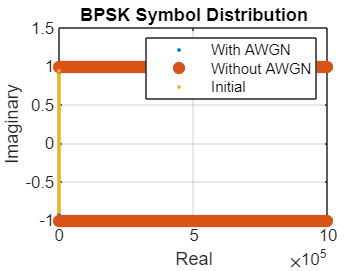

% Visualising symbol distributions
% BPSK
plot(voltageI_BPSK_AWGN(:,11)+1i*voltageQ_BPSK_AWGN(:,11), "."); 
hold on
plot(testVI_BPSK(:,11), ".", MarkerSize=20);
plot(voltageI_BPSK(:,11)+1i*voltageQ_BPSK(:,11), ".");
xlabel("Real"); 
ylabel("Imaginary")
title("BPSK Symbol Distribution")
legend("With AWGN", "Without AWGN", "Initial")
grid on
hold off

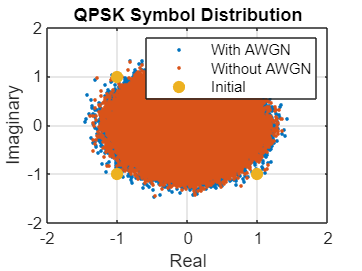


% QPSK
plot(voltageI_QPSK_AWGN(:,11)+1i*voltageQ_QPSK_AWGN(:,11), "."); 
hold on
plot(voltageI_QPSK(:,11)+1i*voltageQ_QPSK(:,11), ".");
plot(testVI_QPSK(:,11)+1i*testVQ_QPSK(:,11), ".", MarkerSize=20);
xlabel("Real"); 
ylabel("Imaginary")
title("QPSK Symbol Distribution")
legend("With AWGN", "Without AWGN", "Initial")
grid on
hold off

## CD Compensation

% CD compensation
c = 299792458; % Speed of light in m/s
D = 17; % GVD is ps/nm/km
linkLength = 50e3;
N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
NFFT_BPSK = 2^12; NFFT_QPSK = 2^18;

for i=1:length(SNR_vals)
    voltage_BPSK_CDC(:,i) = OverlapSaveCDC(voltageI_BPSK(:,i)+1i*voltageQ_BPSK(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_BPSK, N_CD);
    voltage_QPSK_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK(:,i)+1i*voltageQ_QPSK(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
    voltage_BPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_BPSK_AWGN(:,i)+1i*voltageQ_BPSK_AWGN(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_BPSK, N_CD);
    voltage_QPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK_AWGN(:,i)+1i*voltageQ_QPSK_AWGN(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
end

### Downsampling

% Downsampling signals
% BPSK
voltageI_BPSK_CDC = real(voltage_BPSK_CDC(1:SpS:end, :)); voltageQ_BPSK_CDC = imag(voltage_BPSK_CDC(1:SpS:end, :)); % Without AWGN
voltageI_BPSK_AWGN_CDC = real(voltage_BPSK_AWGN_CDC(1:SpS:end, :)); voltageQ_BPSK_AWGN_CDC = imag(voltage_BPSK_AWGN_CDC(1:SpS:end, :)); % With AWGN
testVI_BPSK = testFEOutBPSK_I(1:SpS:end, :); testVQ_BPSK = testFEOutBPSK_Q(1:SpS:end, :); % Test
% QPSK
voltageI_QPSK_CDC = real(voltage_QPSK_CDC(1:SpS:end, :)); voltageQ_QPSK_CDC = imag(voltage_QPSK_CDC(1:SpS:end, :)) % With AWGN

voltageQ_QPSK_CDC =     0.3195    0.3191    0.3197   -0.3136   -0.3184   -0.3138   -0.3137    0.3186    0.3188   -0.3127    0.3184
    0.3195    0.3187    0.3193    0.3136    0.3135   -0.3198   -0.3135    0.3136    0.3183   -0.3195    0.3187
   -0.3127   -0.3143   -0.3131   -0.3137    0.3187   -0.3123    0.3136   -0.3187    0.3130    0.3196   -0.3194
    0.3129    0.3190   -0.3188   -0.3189   -0.3188    0.3191    0.3189    0.3189   -0.3182    0.3133   -0.3191
   -0.3130    0.3129    0.3194   -0.3132    0.3195   -0.3134   -0.3136   -0.3141    0.3189   -0.3137   -0.3186
    0.3187    0.3128    0.3187    0.3133   -0.3142    0.3140    0.3131   -0.3136   -0.3134    0.3140   -0.3190
   -0.3192    0.3130   -0.3135   -0.3197   -0.3186    0.3184   -0.3134   -0.3131    0.3181    0.3183    0.3139
    0.3137    0.3196   -0.3197    0.3134    0.3146   -0.3190    0.3194   -0.3132   -0.3187   -0.3149   -0.3181
   -0.3138   -0.3192   -0.3135    0.3190   -0.3191    0.3141   -0.3139   -0.3195   -0.3138  

voltageI_QPSK_AWGN_CDC = real(voltage_QPSK_AWGN_CDC(1:SpS:end, :)); voltageQ_QPSK_AWGN_CDC = imag(voltage_QPSK_AWGN_CDC(1:SpS:end, :)); % With AWGN
testVI_QPSK = testFEOutQPSK_I(1:SpS:end, :); testVQ_QPSK = testFEOutQPSK_Q(1:SpS:end, :); % Test

% Visualising symbol distribution before and after CD compensation

### Decoding and Decision

% Decoding recieved symbols

% BPSK
% Test voltages
testSymbolsBPSK = testVI_BPSK + 1i*testVQ_BPSK;
testIntsBPSK = pskdemod(testSymbolsBPSK, 2);
testBitsBPSK = int2bit(testIntsBPSK, 1);
biterr(testBitsBPSK, sourceBitsBPSK)

ans = 0


% WITHOUT AWGN
decodedSymbolsBPSK = voltageI_BPSK_CDC + 1i*voltageQ_BPSK_CDC; 
decodedIntsBPSK = pskdemod(decodedSymbolsBPSK, 2);
decodedBitsBPSK = int2bit(decodedIntsBPSK, 1);

% WITH AWGN
decodedSymbolsBPSK_AWGN = voltageI_BPSK_AWGN_CDC + 1i*voltageQ_BPSK_AWGN_CDC; 
decodedIntsBPSK_AWGN = pskdemod(decodedSymbolsBPSK_AWGN, 2);
decodedBitsBPSK_AWGN = int2bit(decodedIntsBPSK_AWGN, 1);

% --------------------------------------------------------------------------------------------

% QPSK
%Test Votlages
testSymbolsQPSK = testVI_QPSK + 1i*testVQ_QPSK;
testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
testBitsQPSK = int2bit(testIntsQPSK, 2);
biterr(testBitsQPSK, sourceBitsQPSK)

ans = 0


% WITHOUT AWGN
decodedSymbolsQPSK = voltageI_QPSK_CDC + 1i*voltageQ_QPSK_CDC;
decodedIntsQPSK = pskdemod(decodedSymbolsQPSK, 4, pi/4);
decodedBitsQPSK = int2bit(decodedIntsQPSK, 2);

% WITH AWGN
decodedSymbolsQPSK_AWGN = voltageI_QPSK_AWGN_CDC + 1i*voltageQ_QPSK_AWGN_CDC; 
decodedIntsQPSK_AWGN = pskdemod(decodedSymbolsQPSK_AWGN, 4, pi/4);
decodedBitsQPSK_AWGN = int2bit(decodedIntsQPSK_AWGN, 2);


### Evaluating BER

% Calculating BER 
for i=1:length(SNR_vals)
    [~, BER_BPSK(i,1)] = biterr(decodedBitsBPSK(:,i), sourceBitsBPSK(:,i));
    [~, BER_QPSK(i,1)] = biterr(decodedBitsQPSK(:,i), sourceBitsQPSK(:,i));
    [~, BER_BPSK_AWGN(i,1)] = biterr(decodedBitsBPSK_AWGN(:,i), sourceBitsBPSK(:,i));
    [~, BER_QPSK_AWGN(i,1)] = biterr(decodedBitsQPSK_AWGN(:,i), sourceBitsQPSK(:,i));
end

% Visualising variation of BER with different SNR values
% semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
% hold on
semilogy(SNR_vals(1:11), BER_BPSK(1:11), "-o");
title("BER vs SNR for BPSK")
xlabel("SNR / dB")
ylabel("BER")
legend("Theoretical Min", "Simulation")

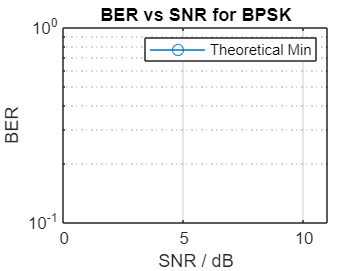

grid on

% hold off

% semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
% hold on
semilogy(SNR_vals(1:11), BER_QPSK(1:11), "-o");
title("BER vs SNR for QPSK")
xlabel("SNR / dB")
ylabel("BER")
legend("Theoretical Min", "Simulation")

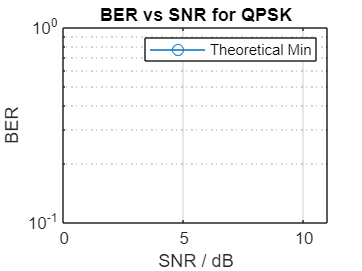

grid on

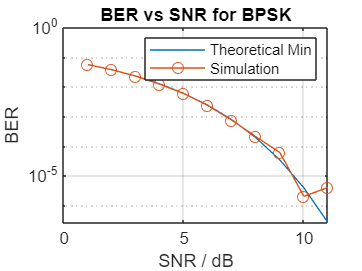

% hold off

semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
hold on
semilogy(SNR_vals(1:11), BER_BPSK_AWGN(1:11), "-o");
title("BER vs SNR for BPSK")
xlabel("SNR / dB")
ylabel("BER")
legend("Theoretical Min", "Simulation")
grid on
hold off 

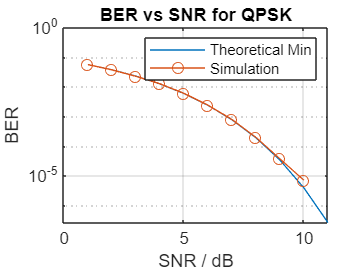


semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
hold on
semilogy(SNR_vals(1:11), BER_QPSK_AWGN(1:11), "-o");
title("BER vs SNR for QPSK")
xlabel("SNR / dB")
ylabel("BER")
legend("Theoretical Min", "Simulation")
grid on
hold off